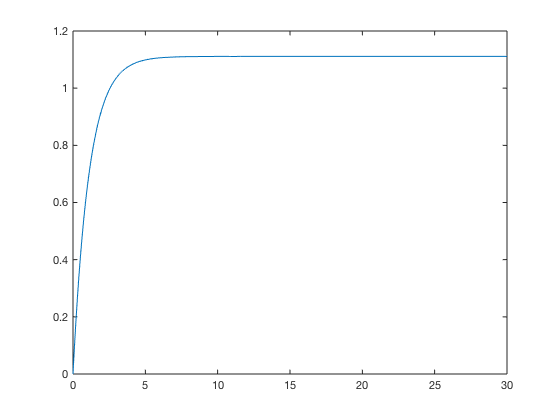

f = @(x,u) sin(x) + u + 0.1*x;
k = 0.5;
u = @(x,r,rdot) -sin(x) + rdot - (x - r); %ENTER CONTROLLER HERE
r = 1;
rdot = 0;
x0 = 0;
tfinal = 30;
sol  = ode45(@(t,x)f(x,u(x,r,rdot)),[0,tfinal],[x0]);
t = 0:0.1:tfinal;
x = deval(sol,t);
plot(t,x)

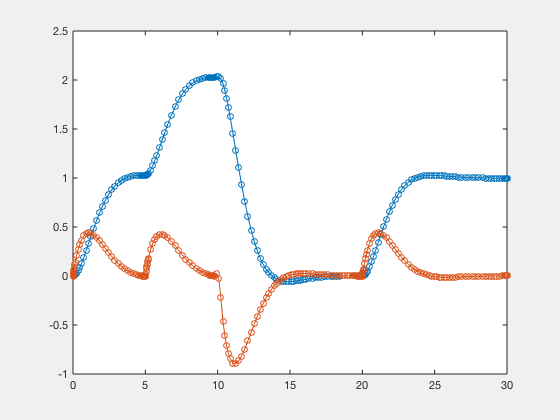


d1 = 1;
d2 = 1.5;
f_ref = @(r,rdot,ur) [rdot;-d1*r-d2*rdot+d1*ur];
step = @(t) t>=0;
ur = @(t) step(t)+step(t-5)-2*step(t-10)+step(t-20);

ode45(@(t,x)f_ref(x(1),x(2),ur(t)),[0,tfinal],[0;0]);

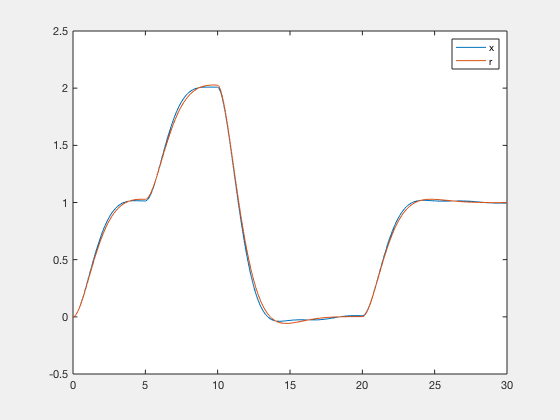


f_int = @(x,r)x-r;
k1 = 0.5;
k2 = 2; 
u = @(x,r,rdot,eint)-sin(x)-k*(x-r)-k2*eint+rdot;
x0 = 0;
tfinal = 30;
F = @(x,r,rdot,eint,ur)[f(x,u(x,r,rdot,eint));f_ref(r,rdot,ur);f_int(x,r)];
sol  = ode45(@(t,y)F(y(1,:),y(2,:),y(3,:),y(4,:),ur(t)),[0,tfinal],[x0;0;0;0]);
t = 0:0.1:tfinal;
sol = deval(sol,t);
x = sol(1,:);
r = sol(2,:);
rdot = sol(3,:);
plot(t,x,t,r)
legend('x','r')